Tutorial walking through the process of generating a 3D model from Viking's disc annotations (which are defined by XYZ location and radius). 

Note: this is a work in progress! 

So far, this is also focused only on the primary rendering algorithm, which I think is relatively straightforward. Under rare circumstances, this fails and the code resorts to a second algorithm, which is messier but more robust. Maybe one day I will be comfortable enough with quaternions to explain that one. 

Before the rendering code reaches this point, I divide the neuron into segments (so I don't have to bother with rendering branches). These are identified by converting the annotations and the links between them are converted into a graph of nodes and edges. Then, depth first search is used to divide up the graph into segments without branches.

Resources:

Dunn & Parberry - 3D Math Primer for Graphics and Game Development

The code in sbfsem.render.Cylinder borrows from and/or was inspired by code from Github/Matlab File Exchange, noteably the matGeom toolbox, plot3t, gencyl, quaternion

% Clear out the main variables
clear normal X Y Z DATA mag R N FV

% Setup some prefs
set(0, 'DefaultAxesBox', 'off',...
    'DefaultAxesFontName', 'Roboto',...
    'DefaultAxesLineWidth', 1);
red = hex2rgb('ff4040');
green = [0 0.8 0.5];
blue = [0 0.3 1];

% So fminsearch will display fit results
options = optimset('Display', 'final');

A render is made up **faces** and **vertices**. The vertices are the points making the render's structure and the faces are the connections between the vertices.

% Each annotation is rendered as a circle consisting of N vertices
N = 10;
% The locations of the N vertices, in degrees
angles = 0:(360/N):359.999;

% Make some data
X = [1 2 2 1 1]';
Y = ones(size(X));
% Y = (1:numel(X))';
Z = (1:numel(Y))';
R = 2 + zeros(size(X))';
%R = [2 2 2 1 1 2 3 4]';
DATA = [X,Y,Z];

% Make a color map for the data
co = pmkmp(numel(X), 'cubicl');

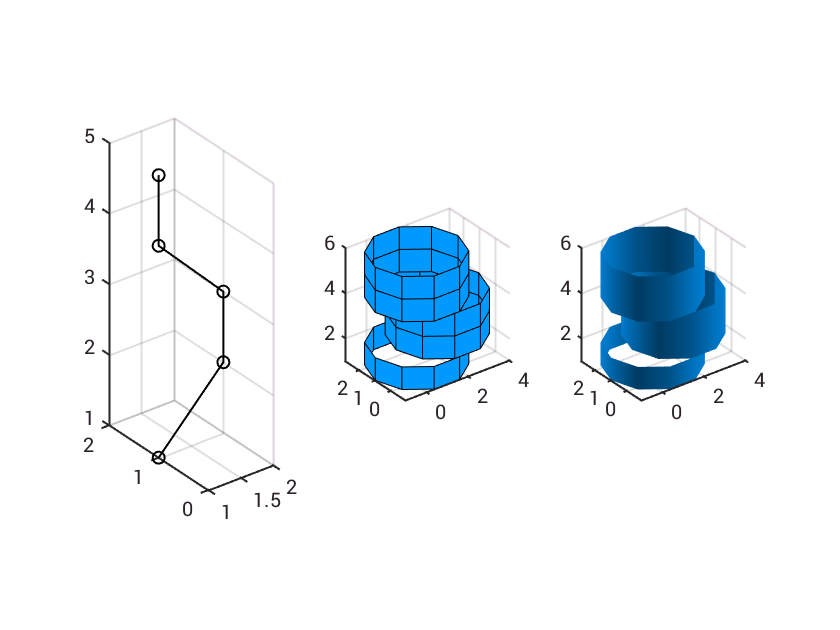

% Display the data:
figure(); subplot(131);
plot3(X,Y,Z,'-ok', 'LineWidth', 1);
grid on; view(3); axis tight equal;

% Using matlab's cylinder
subplot(132); hold on;
for i = 1:numel(X)
    [x, y, z] = cylinder(R(i), N);
    % Move to the correct X,Y,Z
    surf('XData', x + X(i), 'YData', y + Y(i),...
        'ZData', z + Z(i), 'FaceColor', [0, 0.6, 1]);
end
grid on; view(3); axis tight equal;

% Quick demo of how to add lighting
subplot(133); hold on;
for i = 1:numel(X)
    [x, y, z] = cylinder(R(i), N);
    % Move to the correct X,Y,Z
    surf('XData', x + X(i), 'YData', y + Y(i),...
        'ZData', z + Z(i), 'FaceColor', [0, 0.6, 1]);
end
grid on; view(3); axis tight equal;
lighting gouraud; lightangle(45,30); lightangle(225,30);
set(findall(gca, 'Type', 'surf'), 'EdgeColor', 'none');

Next we take the difference between each point. As we'll see later, translating a mesh is trivial so the absolute XYZ coordinates are unnecessary for building the mesh. The important part at this stage is the location of each point relative to the points it's connected to. When thinking about points relative to each other, it's helpful to separate the distance into two isolated quantities: **direction** and **magnitude.**

Let $\vec{v}$ be a vector (think line segment) between points **p** and **q**. To relate things back to the EM, **p** and **q** are 3-dimensional: $\mathbf{p}=(p_1, p_2, p_3)$. These 3 numbers are the X, Y and Z coordinates of an annotation. 

The **magnitude** or **L2 norm** of a vector ignores direction and describes only the length of the vector:


$$\parallel v\parallel = \sqrt{\sum_{i=1}^n v_i^2} = \sqrt{v_1^2 + v_2^2+\dots+v_{n-1}^2+v_n^2}$$


In 3D, this is formula is:


$$\parallel v \parallel = \sqrt{v_x^2+v_y^2+v_z^2}$$


The distance between two points is similar, as it is the length of the line segment needed to connect two points. This is the **Euclidean distance. **For points $(p_x, p_y, p_z)$ and $(q_x, q_y, q_z)$, this is calculated as:


$$\parallel\vec{v}\parallel=\sqrt{(p_1-q_1)^2 + (p_2-q_2)^2 + (p_3-q_3)^2}$$


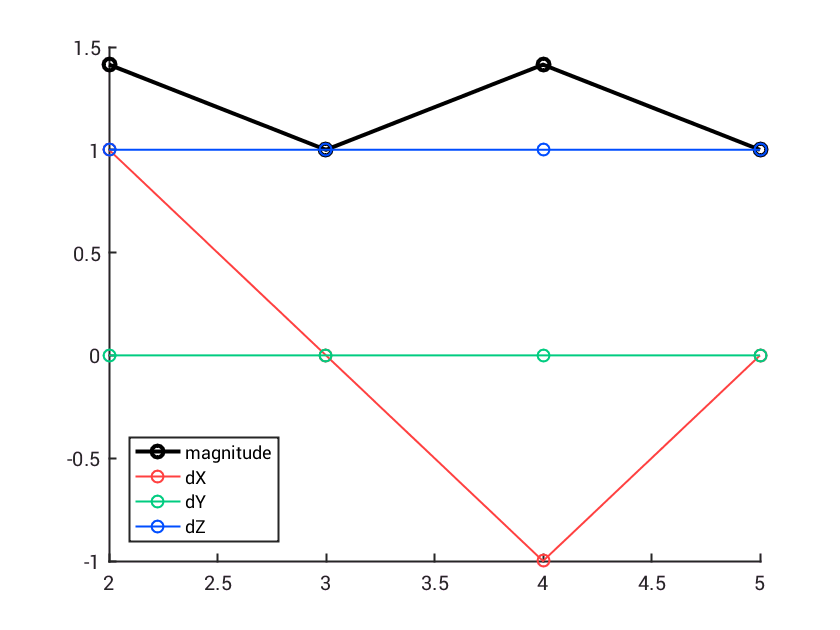

% Euclidean distance between points.
mag = sqrt((diff(X)).^2 + (diff(Y)).^2 + (diff(Z)).^2);

figure('Renderer', 'painters'); hold on;
plot(2:numel(R), mag, '-ok', 'LineWidth', 2);
plot(2:numel(R), diff(X), '-o', 'Color', red, 'LineWidth', 1);
plot(2:numel(R), diff(Y), '-o', 'Color', green, 'LineWidth', 1);
plot(2:numel(R), diff(Z), '-o', 'Color', blue, 'LineWidth', 1);
legend('distance', 'dX', 'dY', 'dZ')
set(legend, 'Location', 'SouthWest')

% Buffer distance between two line pieces
bufferDist = max(R);   
if (min(mag)/2.2) < bufferDist
    bufferDist = min(mag)/2.2;
    fprintf('Reset bufferDist to %.2g from %2.g\n',...
    	max(R), bufferDist);
end

Reset bufferDist to 2 from 0.5


Next, a metric to describe only the **direction** of the line segment between two points. These are called **unit vectors **or** normals** because the magnitude/length is normalized (aka 1). Because this metric doesn't care about the distance between the two points, it's convinient to just set them all equal to one.


$$v_{norm}=\frac{v}{\parallel v \parallel}$$


To isolate the direction, this just divides out the magnitude.

% The x, y and z distance between each point. Also can be thought 
% of as the vectors between each set of points.
vec = diff(DATA);
% Now normalize the vectors.
normal = vec./(mag*ones(1,3));
% I add a point to the end to keep the total number of points
% constant throughout the code.
normal = [normal; normal(end,:)];

% The distance between each point (vec) has 3 points, XYZ.
% The magnitude has only 1 point. Matlab wants the matrix 
% sizes to match, so the *ones(1,3) bit just turns the 
% 1 magnitude into 3 points, all equal.

% Alternative code
% vec = diff(DATA);
% vec = [vec; vec(end,:)];
% normal = vec ./ (sqrt(vec(:,1).^2 + vec(:,2).^2 ...
%                + vec(:,3).^2) * ones(1,3));

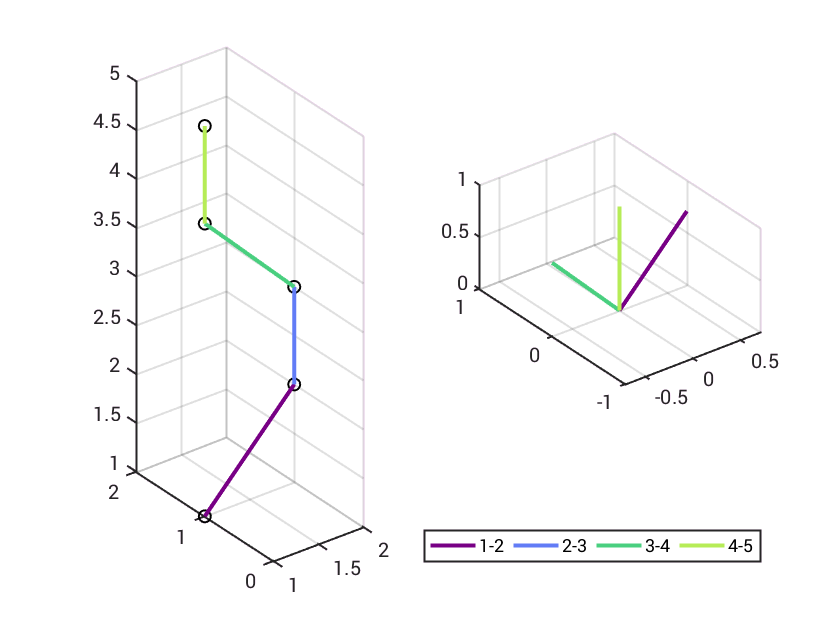

% Display the normals and compare to the original data
figure(); subplot(121); hold on;
plot3(X, Y, Z, 'ok', 'LineWidth', 1);
for i = 1:numel(X)-1
    plot3(X(i:i+1), Y(i:i+1), Z(i:i+1),...
        'Color', co(i,:), 'LineWidth', 2);
end
view(3); grid on; axis tight equal
% Note if normals are equal, only the last one plotted will be visible
subplot(122); hold on;
legendEntry = cell(0,1);
for i = 1:size(normal,1)-1
    plot3([0 normal(i,1)], [0 normal(i,2)], [0 normal(i,3)],...
        'Color', co(i,:), 'LineWidth', 2);
    legendEntry = cat(1, legendEntry, sprintf('%u-%u', i, i+1));
end
view(3); grid on; axis tight equal
legend(legendEntry, 'Orientation', 'Horizontal'); 
set(legend, 'Location', 'SouthOutside')

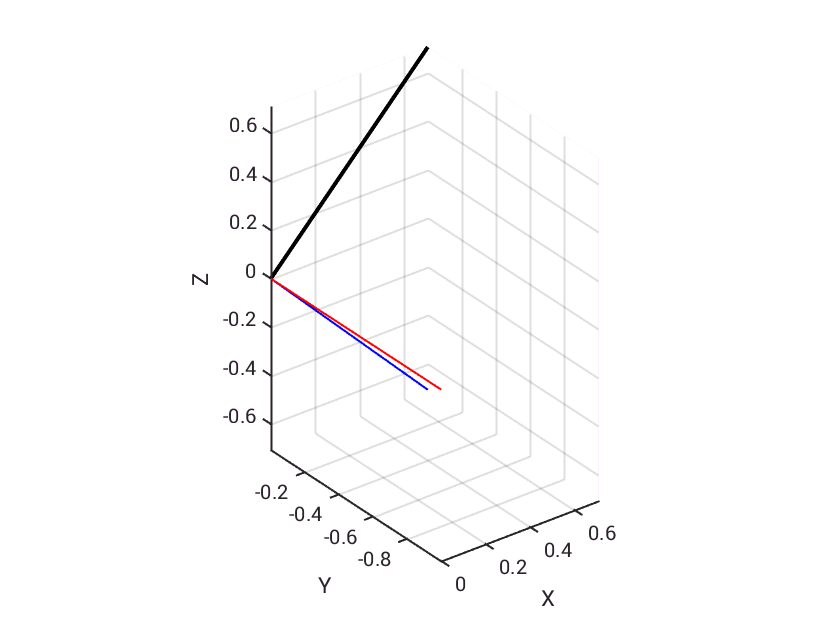

% Get 3D circle coordinates of first circle/cylinder
[a,b] = getAB(normal(1,:));

figure(); hold on;
plot3([0 normal(1,1)], [0 normal(1,2)], [0 normal(1,3)],...
    'k', 'LineWidth', 2);
plot3([0 a(1)], [0 a(2)], [0 a(3)], 'r', 'LineWidth', 1);
plot3([0 b(1)], [0 b(2)], [0 b(3)], 'b', 'LineWidth', 1);
grid on; view(3); axis tight equal;
xlabel('X'); ylabel('Y'); zlabel('Z')

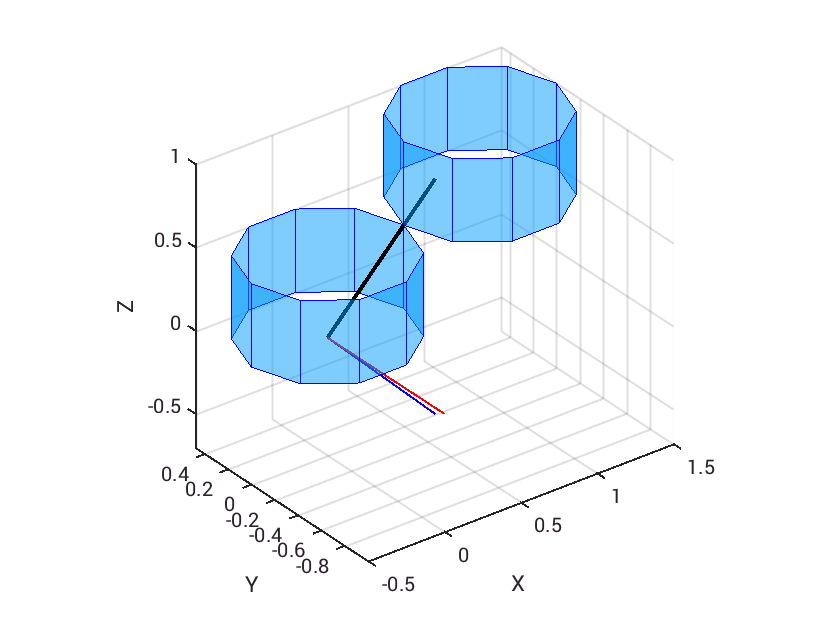

% To understand this, show where the annotations are
% Rendered as unit cylinders bc radius isn't taken into account here
[x,y,z] = cylinder(0.5, N);
surf(x, y, z/2, 'FaceColor', [0 0.6 1], 'FaceAlpha', 0.5, 'EdgeColor', 'b');
surf(x+(X(2)-X(1)), y+(Y(2)-Y(1)), z/2+0.5,...
    'FaceColor', [0 0.6 1], 'FaceAlpha', 0.5, 'EdgeColor', 'b');

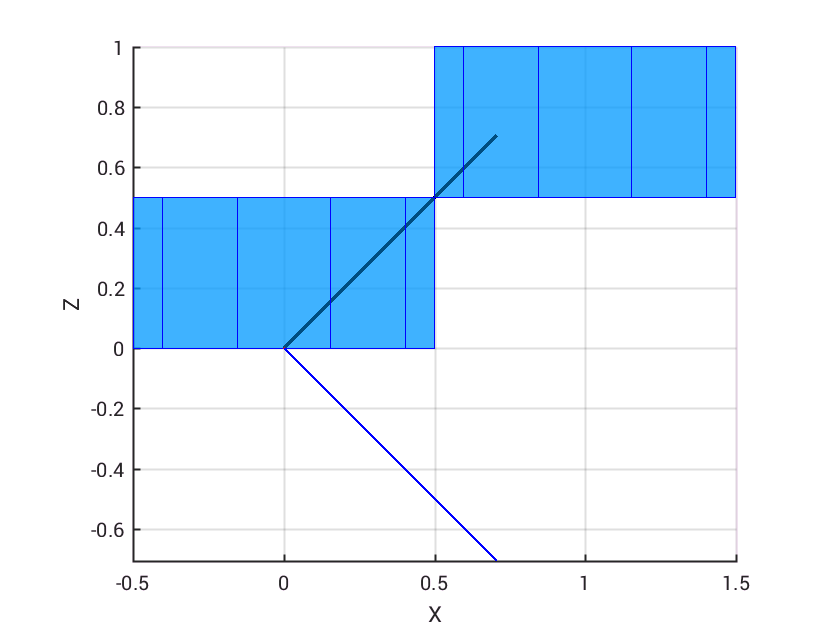

% Helpful to see this from a few different angles
view(0,0)

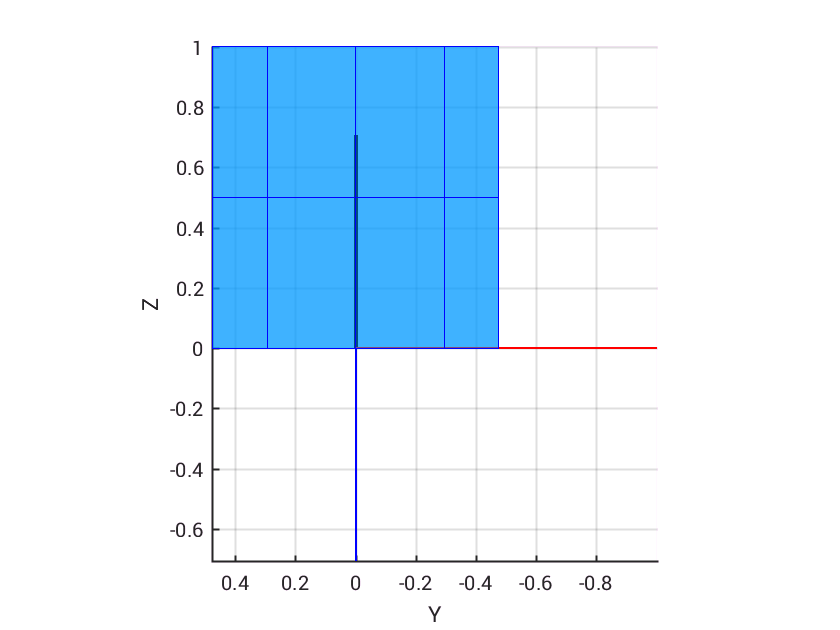

view(-90,0)

Next we return the vertices (points) defining a circle orthogonal to the line connecting two annotations. (the output of `normalCircle.m`). This function also includes an argument called  `angleOffset` which defines an in-plane rotation of the 2d circle coordinates. This in plane rotation won't change the circle itself, it just rotates the vertices around so they line up with the vertices on the previous circle. This becomes important when the vertices are connected to form the faces of the final render.

% In plane rotation of 2d circle coordinates. The vertices
% on two circles are connected to create faces. This rotates
% the vertices on a circle so they align better with the points
% on a neighboring circle.
angleOffset = 0;
% And the coordinates themselves
circum = normalCircle(angles, angleOffset, a, b);

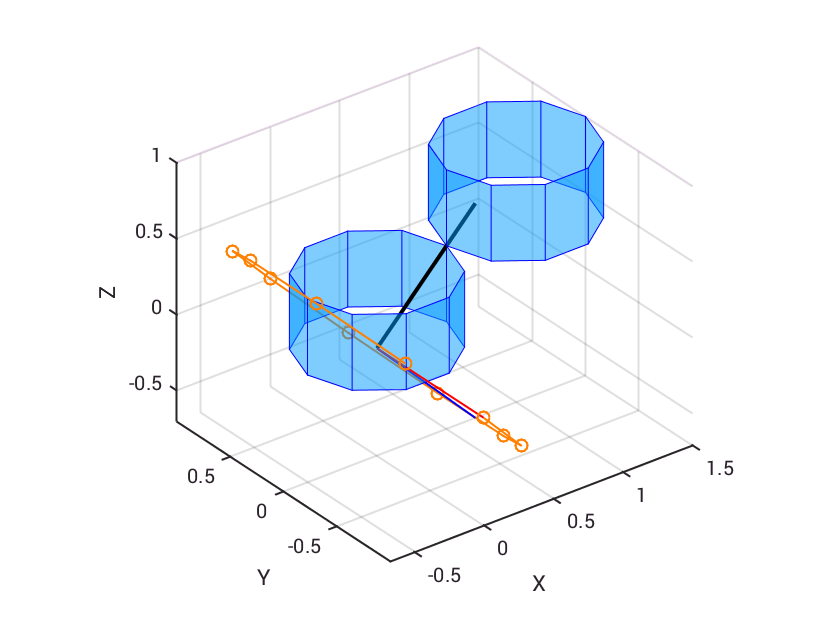

view(3)
plot3(circum(:,1), circum(:,2), circum(:,3), '-o',...
    'LineWidth', 1, 'Color', [1 0.5 0]);
axis tight equal;
set(gcf, 'Renderer', 'painters')

% Track the number of cylinders in region
numCylinders = 0;
% List to store vertex points
FV.vertices = zeros(N * length(DATA), 3);

% Add a half sphere at line start
for j = 5:-0.5:1
    % Translate the circle on it's position on the line
    r = sqrt(1 - (j/5)^2);
    iCirc = r * R(1) * circum + ones(N,1) * ...
        (DATA(1,:) - (j/5) * bufferDist * normal(1,:));
    % Create vertex list
    numCylinders = numCylinders + 1;
    FV.vertices(((numCylinders-1)*N+1):(numCylinders*N),:) =...
        [iCirc(:,1), iCirc(:,2), iCirc(:,3)];
end

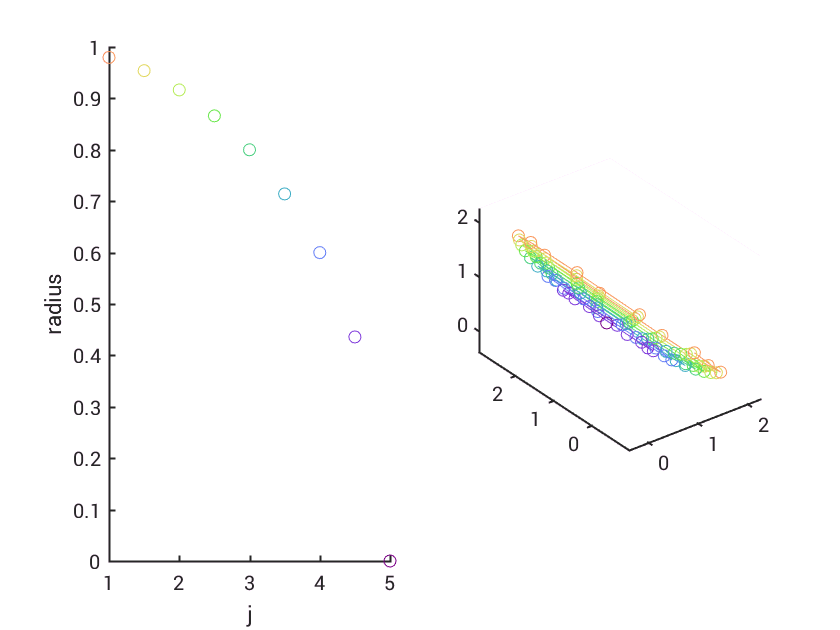

% This repeats the previous block and displays output
figure(); hold on;
ax1 = subplot(121); hold on;
ax2 = subplot(122); hold on;
co = pmkmp(numel(5:-0.5:1), 'cubicl');
numColor = 0;

all_r = [];
for j = 5:-0.5:1
    numColor = numColor + 1;
    r = sqrt(1 - (j/5)^2);
    plot(ax1, j, r, 'o', 'Color', co(numColor,:));
    iCirc = r * R(1) * circum + ones(N,1) *...
        (DATA(1,:) - (j/5) * bufferDist * normal(1,:));
    plot3(ax2, iCirc(:,1), iCirc(:,2), iCirc(:,3),...
        '-o', 'Color', co(numColor,:));
end
view(ax2, 3); axis equal
xlabel(ax1, 'j'); ylabel(ax1, 'radius');

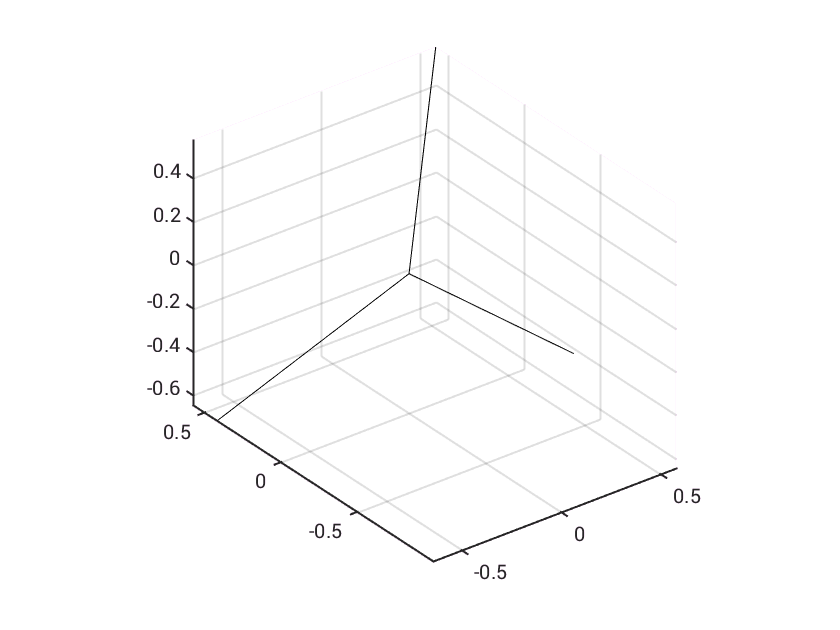

% Make a 3 point circle to be rotated
% and aligned with the next circle
circmo = normalCircle([0 120 240], 0, a, b);

figure(); hold on;
for i = 1:size(circmo,1)
    plot3([0 circmo(i,1)], [0 circmo(i,2)], [0 circmo(i,3)], 'k');
end
view(3); axis equal; grid on;

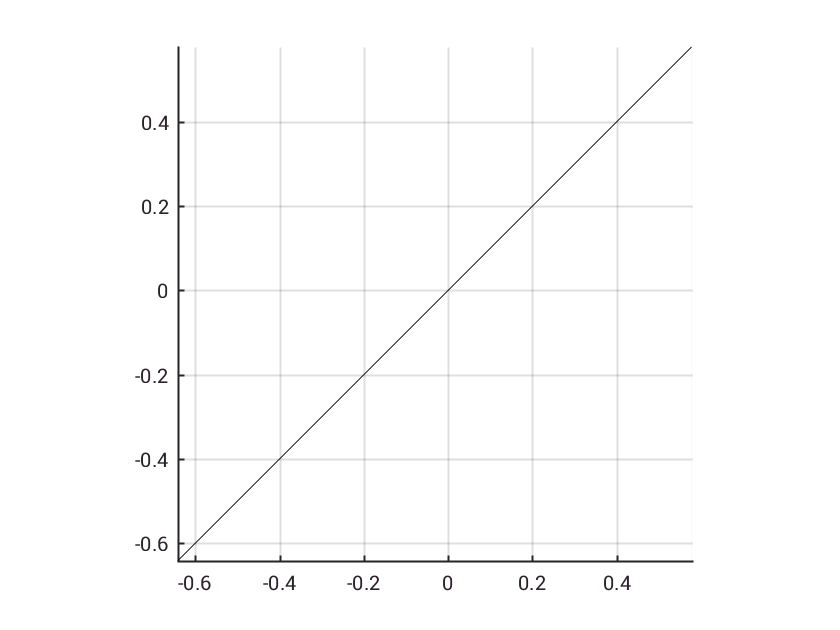

view(0,0);

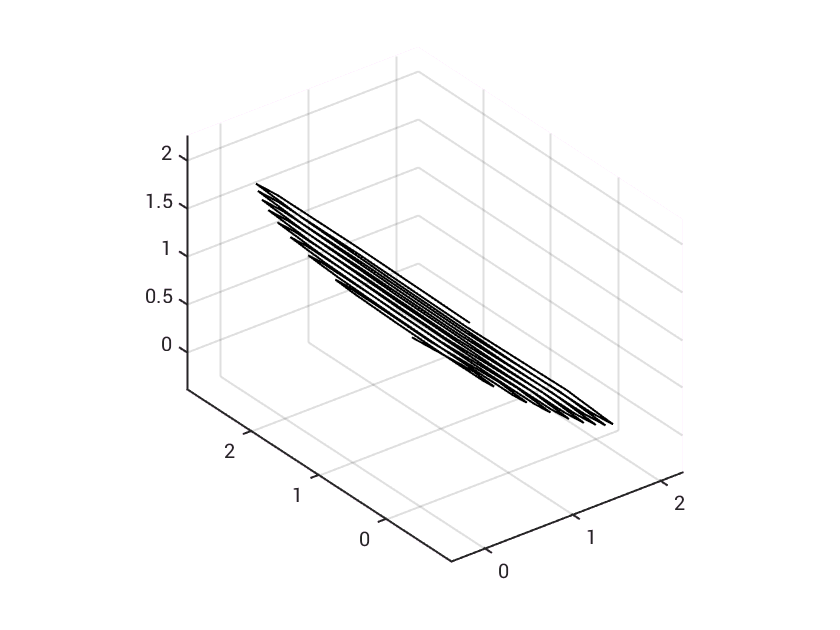

% This plot will track the progress of vertices
ax = axes('Parent', figure); hold on;
for i = 1:size(FV.vertices,1)
    plot3(ax, FV.vertices(:,1), FV.vertices(:,2), FV.vertices(:,3),...
        'k', 'LineWidth', 1);
end
view(ax, 3); axis tight equal; grid on;

Wrapped in a for loop:

i = 1; % Line Segment
% Current data point
iNormal = normal(i,:); 
iData = DATA(i,:);
% Next data point
jNormal = normal(i+1,:);

Index exceeds matrix dimensions.


jData = DATA(i+1,:);


Step One: Create a main cylinder between two line points.

This is just 2 connected line points, current point and the next

% Calculate the 3D circle coordinates
[a, b] = getAB(iNormal);
circm = normalCircle(angles, angleOffset, a, b);
% This is the same as the last output of normalCircle

% There are two steps here
% First circm is scaled by the radius to be appropriately sized
% Next, it is translated by the data points
circmp = circm*R(i)...
    + ones(N,1)*(iData+bufferDist*iNormal);
numCylinders = numCylinders + 1;
FV.vertices(((numCylinders-1)*N+1):(numCylinders*N),:) =...
    [circmp(:,1), circmp(:,2), circmp(:,3)];

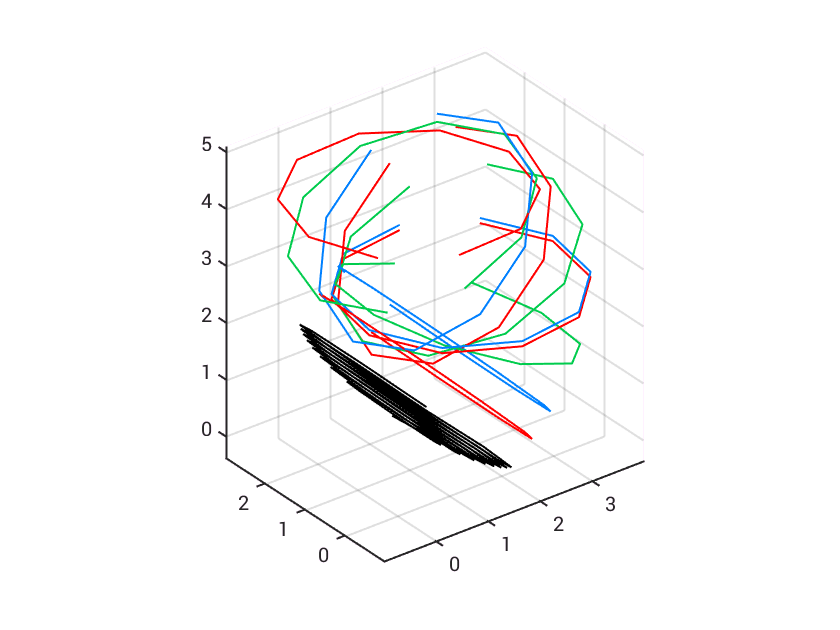

% Add to existing plot
plot3(ax, circmp(:,1), circmp(:,2), circmp(:,3),...
    'Color', 'r', 'LineWidth', 1);

% Repeat the steps above
% But here it's working back from the next data points
circmp = circm * R(i+1) + ...
    ones(N,1) * (jData - bufferDist*iNormal);
numCylinders = numCylinders + 1;
FV.vertices(((numCylinders-1)*N+1):(numCylinders*N),:) =...
    [circmp(:,1), circmp(:,2), circmp(:,3)];

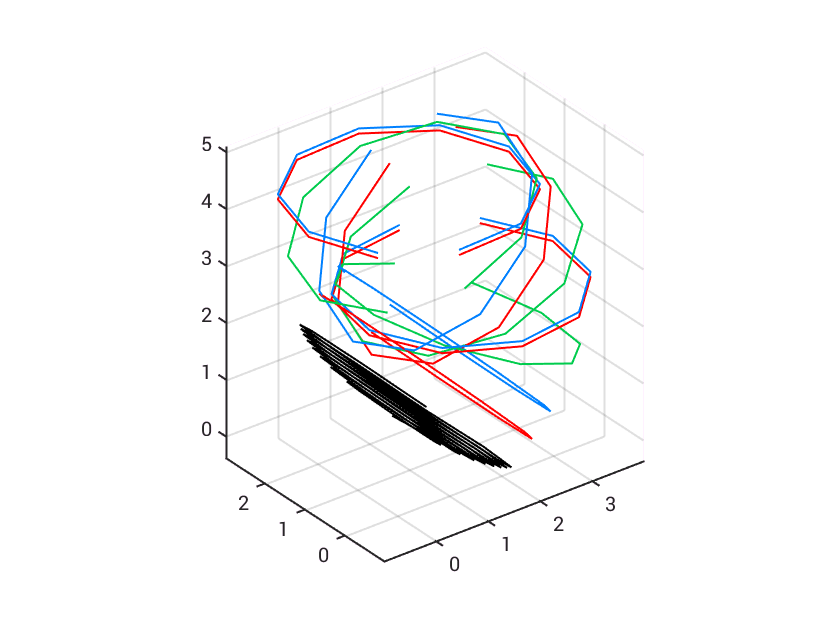

% Add to existing plot
plot3(ax, circmp(:,1), circmp(:,2), circmp(:,3),...
    'Color', [0 0.5 1], 'LineWidth', 1);

% Create an in between cicle to smoothly connect the lines
ijNormal = iNormal + jNormal;
ijNormal = ijNormal ./ sqrt(sum(ijNormal.^2));
ijData = 0.5858* jData...
    + 0.4142*(0.5*((jData + bufferDist*jNormal)...
    + (jData - bufferDist*iNormal)));

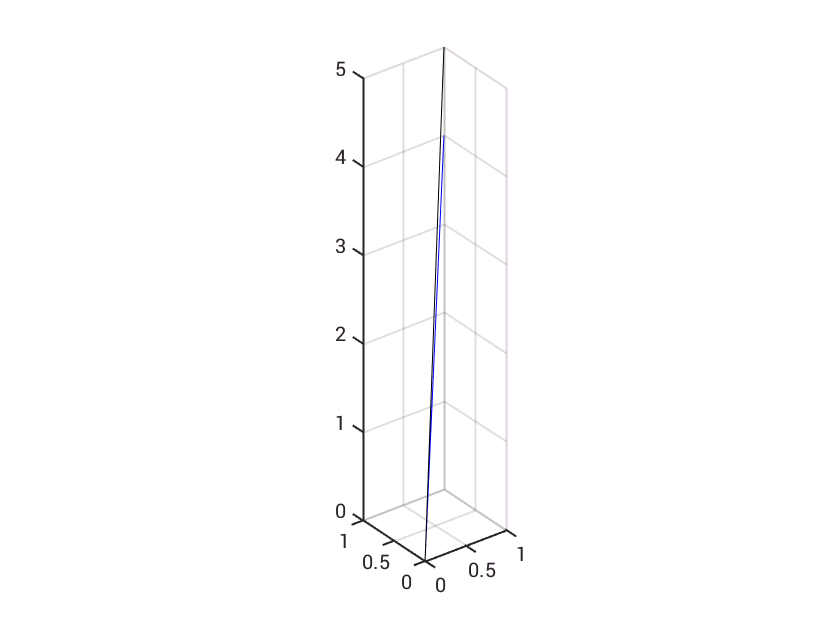

% Display the normals (Not particularly helpful)
figure(); hold on;
plot3([0 iData(1)], [0 iData(2)], [0 iData(3)], 'b');
plot3([0 jData(1)], [0 jData(2)], [0 jData(3)], 'r');
plot3([0 ijData(1)], [0 ijData(2)], [0 ijData(3)], 'k');
view(3); axis equal; grid on;

% Rotate the circle coordinates in plane to align with the 
% previous circle by minimizing the distance between the
% coordinates of the two circles (each with 3 coordinates).
[a, b] = getAB(ijNormal);

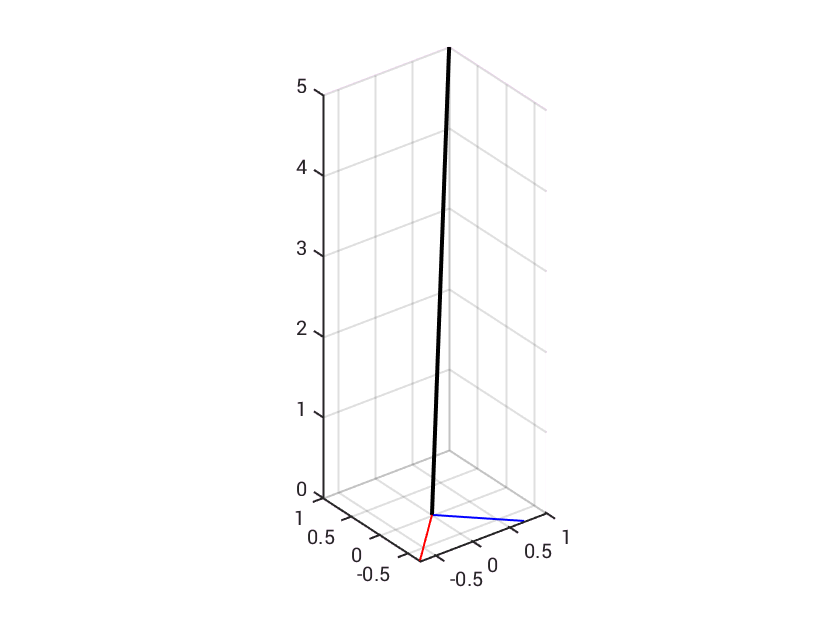

% Display as well
figure(); hold on;
plot3([0 a(1)], [0 a(2)], [0 a(3)], 'r', 'LineWidth', 1);
plot3([0 b(1)], [0 b(2)], [0 b(3)], 'b', 'LineWidth', 1);
plot3([0 ijData(1)], [0 ijData(2)], [0 ijData(3)],...
    'k', 'LineWidth', 2);
view(3); axis equal; grid on;

% Actual minimization referenced above
[angleOffset, ~, exitFlag] = fminsearch(...
    @(j) minimizeRot([0 120 240], circmo, 1, a, b),...
    angleOffset, options);

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



% Not very exiting... the angle offset was already good
fprintf('Angle offset = %.2g\n', angleOffset);

Angle offset = -3.3e+02


% If the exit flag shows a failure to converge,
% we switch algorithms.. this doesn't happen too often
fprintf('Exit flag = %u\n', exitFlag);

Exit flag = 1


% Keep a 3 point circle for rotation alignment with the
% next circle. Redundant now but will be important when
% minimizeRot does find a different angle offset
[a, b] = getAB(ijNormal);
circmo = normalCircle([0 120 240], angleOffset, a, b);

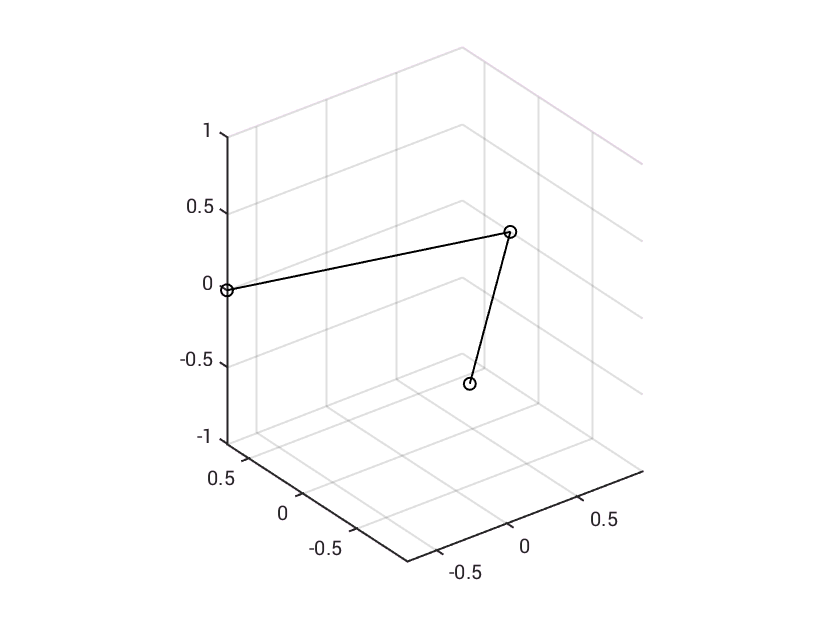

figure(); hold on;
plot3(circmo(:,1), circmo(:,2), circmo(:,3),...
    '-ok', 'LineWidth', 1);
    view(3); grid on; axis equal;

% Calculate the 3D circle coordinates
circm = normalCircle(angles, angleOffset, a, b);
circmp = circm*R(i+1) + ones(N,1)*(ijData);
% Add to vertices and cylinder count
numCylinders = numCylinders + 1;
FV.vertices(((numCylinders-1) * N+1): (numCylinders*N), :) = ...
    [circmp(:,1), circmp(:,2), circmp(:,3)];

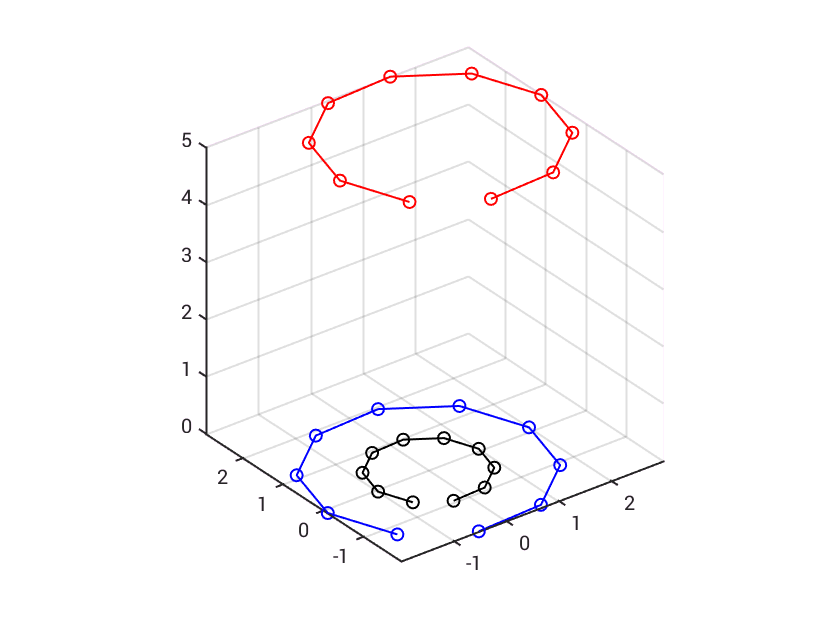

% Breaking down the last two lines:
figure(); hold on;
% Unit circle (2D) located at Z = 0
plot3(circm(:,1), circm(:,2), circm(:,3), '-ok', 'LineWidth', 1);
view(3); axis equal tight; grid on
% Scaled
tmp = circm*R(i+1);
plot3(tmp(:,1), tmp(:,2), tmp(:,3), '-ob', 'LineWidth', 1);
% Translated
tmp = tmp + ones(N,1)*(ijData);
plot3(tmp(:,1), tmp(:,2), tmp(:,3), '-or', 'LineWidth', 1);

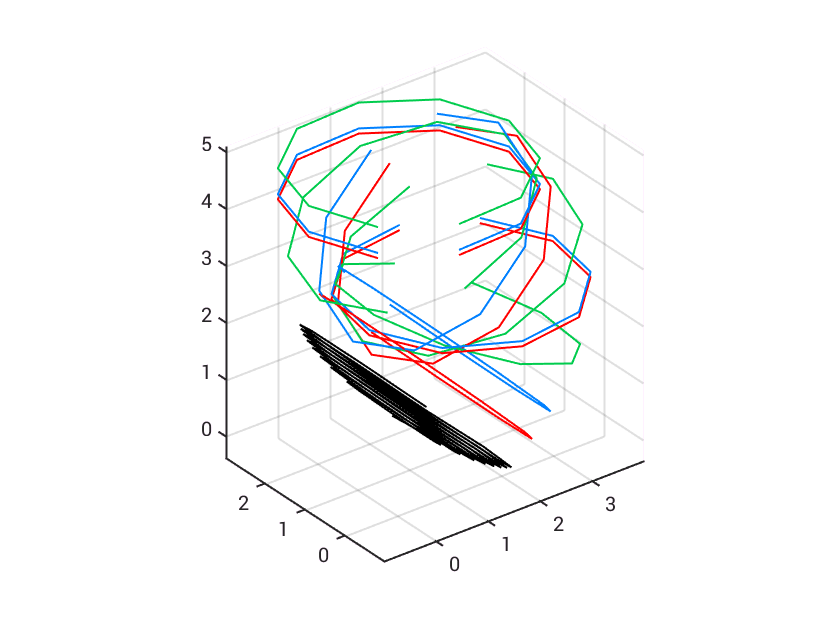

% Add to existing plot
    plot3(ax, circmp(:,1), circmp(:,2), circmp(:,3),...
        'Color', [0 0.8 0.3], 'LineWidth', 1);

% Rotate circle coordinates in the plane to align
% with the previous circle by minimizing distance
% between the coordinates of 2 circles (each with
% 3 coordinates).
[a, b] = getAB(jNormal);
[angleOffset, ~, exitFlag] = fminsearch(...
    @(j) minimizeRot([0, 120, 240], circmo, j, a, b),...
    angleOffset, options);

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



fprintf('Angle offset to %.2f\n', angleOffset);

Angle offset to -330.09


fprintf('Exit flag = %u\n', exitFlag);

Exit flag = 1


if exitFlag == 0
    gencylFlag = 0;
end

% Keep circle for rotation alignment with next circle
% (occurs in next loop)
circmo = normalCircle([0, 120, 240], angleOffset, a, b);

That was 1 loop. Start over and increment `i=1` to `i=2`. Continue until `i=4`.

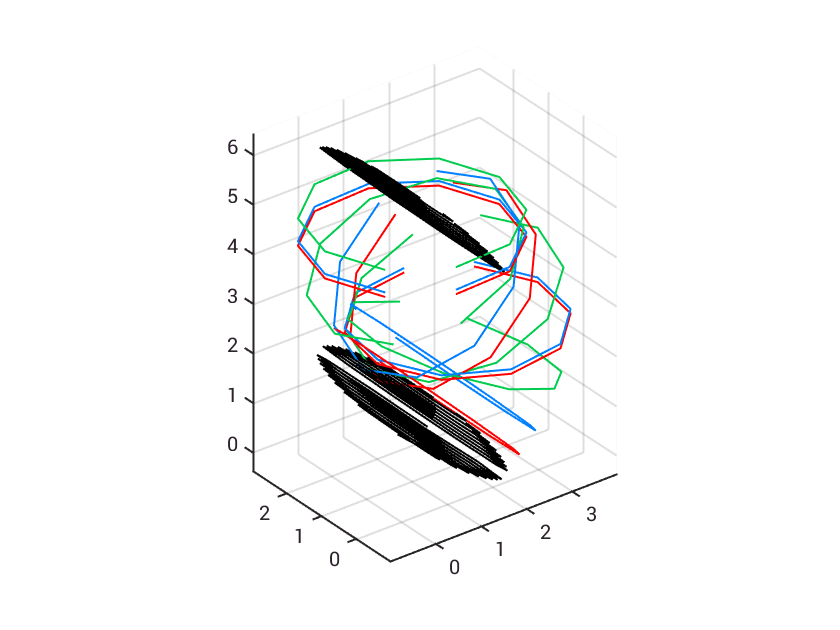

% Add a half sphere at line end
for j = 1:0.5:5
    % Translate the circle on it's position on the line
    r = sqrt(1 - (j/5)^2);
    iCirc = r * R(i+1) * circm + ones(N,1) * ...
        (DATA(i+1,:) + (j/5) * bufferDist * normal(i+1,:));
    % Create vertex list
    numCylinders = numCylinders + 1;
    FV.vertices(((numCylinders-1)*N+1):(numCylinders*N),:) =...
        [iCirc(:,1), iCirc(:,2), iCirc(:,3)];
    plot3(ax, iCirc(:,1), iCirc(:,2), iCirc(:,3),...
        'k', 'LineWidth', 1);
end

That code defined the vertices. The connections between these vertices are called the **faces**. This is a triangle mesh so a face will be defined as 3 connected points. 

This is done by defining the triangulations between 2 neighboring circles, then generalizing to all circles in the render.

Fb = [[1:N, (1:N)+1];...
      [(1:N)+N, (1:N)];...
      [(1:N)+N+1, (1:N)+N+1]]';
disp(Fb)

     1    11    12
     2    12    13
     3    13    14
     4    14    15
     5    15    16
     6    16    17
     7    17    18
     8    18    19
     9    19    20
    10    20    21
     2     1    12
     3     2    13
     4     3    14
     5     4    15
     6     5    16
     7     6    17
     8     7    18
     9     8    19
    10     9    20
    11    10    21



% Notice one of the points is 21. This exceeds the
% number of vertices involved so subtract N
Fb(N,3) = 1 + N;
disp(Fb)

     1    11    12
     2    12    13
     3    13    14
     4    14    15
     5    15    16
     6    16    17
     7    17    18
     8    18    19
     9    19    20
    10    20    11
     2     1    12
     3     2    13
     4     3    14
     5     4    15
     6     5    16
     7     6    17
     8     7    18
     9     8    19
    10     9    20
    11    10    21



Fb(N*2,1) = 1;
Fb(N*2,3) = 1 + N;
disp(Fb)

     1    11    12
     2    12    13
     3    13    14
     4    14    15
     5    15    16
     6    16    17
     7    17    18
     8    18    19
     9    19    20
    10    20    11
     2     1    12
     3     2    13
     4     3    14
     5     4    15
     6     5    16
     7     6    17
     8     7    18
     9     8    19
    10     9    20
     1    10    11



FV.faces = zeros(N*2*(numCylinders-1),3);
for i = 1:numCylinders-1
    FV.faces(((i-1)*N*2+1):((i)*N*2), 1:3) = ...
        (Fb + (i-1)*N);
end

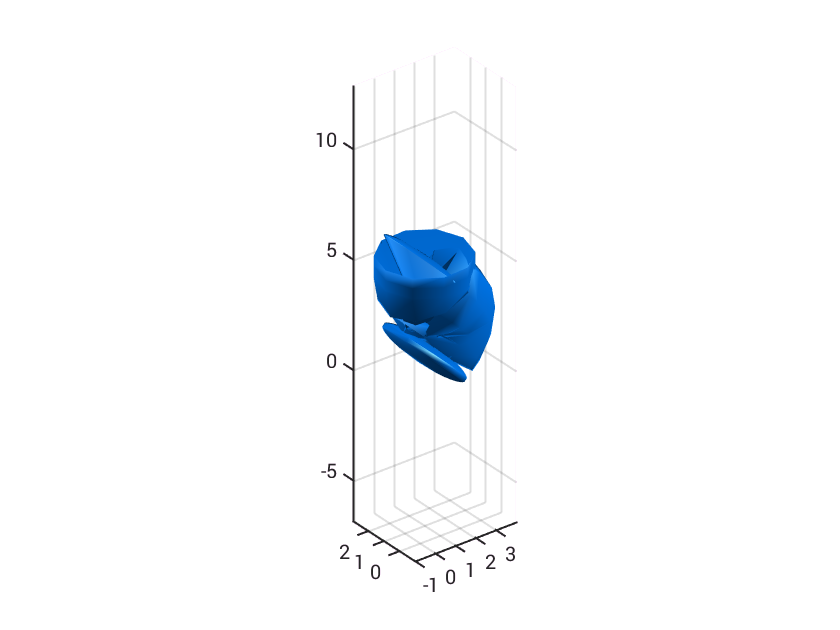

figure(); hold on;
patch('Faces', FV.faces, 'Vertices', FV.vertices,...
    'FaceColor', [0 0.5 1], 'EdgeColor', 'none');
axis equal; grid on; view(3)
lightangle(225,30); lightangle(45,30);
lighting phong